## 1.Load the Data

data=readtable("train.csv")

data = 891×12 table
    PassengerId    Survived    Pclass                             Name                                 Sex        Age    SibSp    Parch      Ticket       Fare       Cabin       Embarked
    ___________    ________    ______    _______________________________________________________    __________    ___    _____    _____    __________    ______    __________    ________

         1            0          3       {'Braund, Mr. Owen Harris'                            }    {'male'  }     22      1        0             NaN      7.25    {0×0 char}     {'S'}  
         2   

## 2.Data Cleaning

summary(data)

Variables:

    PassengerId: 891×1 double

        Values:

            Min           1   
            Median      446   
            Max         891   

    Survived: 891×1 double

        Values:

            Min          0    
            Median       0    
            Max          1    

    Pclass: 891×1 double

        Values:

            Min          1    
            Median       3    
            Max          3    

    Name: 891×1 cell array of character vectors

    Sex: 891×1 cell array of character vectors

    Age: 891×1 double

        Values:

            Min             0.42  
            Median          28    
            Max             80    
            NumMissing      177   

    SibSp: 891×1 double

        Values:

            Min          0    
            Median       0    
            Max          8    

    Parch: 891×1 dou

missingsummary=sum(ismissing(data))

missingsummary =      0     0     0     0     0   177     0     0   230     0   687     2



% fill missing values
data.Age=fillmissing(data.Age,"constant",mean(data.Age,"omitnan"))

data = 891×12 table
    PassengerId    Survived    Pclass                             Name                                 Sex         Age      SibSp    Parch      Ticket       Fare       Cabin       Embarked
    ___________    ________    ______    _______________________________________________________    __________    ______    _____    _____    __________    ______    __________    ________

         1            0          3       {'Braund, Mr. Owen Harris'                            }    {'male'  }        22      1        0             NaN      7.25    {0×0 char}     {'S'}  
    

data.Ticket=fillmissing(data.Ticket,"constant",mean(data.Ticket,"omitnan"))

data = 891×12 table
    PassengerId    Survived    Pclass                             Name                                 Sex         Age      SibSp    Parch      Ticket       Fare       Cabin       Embarked
    ___________    ________    ______    _______________________________________________________    __________    ______    _____    _____    __________    ______    __________    ________

         1            0          3       {'Braund, Mr. Owen Harris'                            }    {'male'  }        22      1        0      2.6032e+05      7.25    {0×0 char}     {'S'}  
    


% Drop rows with missing values
data=data(~ismissing(data.Cabin),:)

data = 204×12 table
    PassengerId    Survived    Pclass                             Name                                 Sex         Age      SibSp    Parch      Ticket       Fare          Cabin          Embarked 
    ___________    ________    ______    _______________________________________________________    __________    ______    _____    _____    __________    ______    _______________    __________

         2            1          1       {'Cumings, Mrs. John Bradley (Florence Briggs Thayer)'}    {'female'}        38      1        0      2.6032e+05    71.283    {'C85'       

data=data(~ismissing(data.Fare),:)

data = 204×12 table
    PassengerId    Survived    Pclass                             Name                                 Sex         Age      SibSp    Parch      Ticket       Fare          Cabin          Embarked 
    ___________    ________    ______    _______________________________________________________    __________    ______    _____    _____    __________    ______    _______________    __________

         2            1          1       {'Cumings, Mrs. John Bradley (Florence Briggs Thayer)'}    {'female'}        38      1        0      2.6032e+05    71.283    {'C85'       

## 3.Exploratory Data Analysis(EDA)

#### summary

summary(data(:,{'Age','Fare'}))

Variables:

    Age: 204×1 double

        Values:

            Min         0.92  
            Median        34  
            Max           80  

    Fare: 204×1 double

        Values:

            Min             0 
            Median     55.221 
            Max        512.33 



#### 3.1 Survival rate by gender

figure
g=gramm("x",data.Sex,"color",data.Survived)

g =   gramm with properties:

     legend_axe_handle: []
      title_axe_handle: []
    facet_axes_handles: []
               results: []


g.stat_bin("geom","bar","dodge",1)

ans =   gramm with properties:

     legend_axe_handle: []
      title_axe_handle: []
    facet_axes_handles: []
               results: [1×1 struct]


g.set_names("x","sex","y","count","color","survived")

ans =   gramm with properties:

     legend_axe_handle: []
      title_axe_handle: []
    facet_axes_handles: []
               results: [1×1 struct]


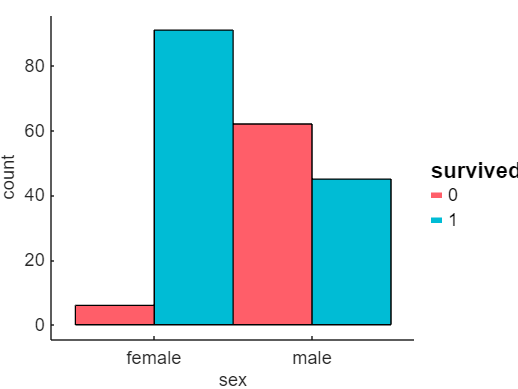

ans =   gramm with properties:

     legend_axe_handle: [1×1 Axes]
      title_axe_handle: []
    facet_axes_handles: [1×1 Axes]
               results: [1×1 struct]


g.draw()

#### 3.2 Age distibution by survival

figure
g=gramm("x",data.Age,"color",data.Survived)

g =   gramm with properties:

     legend_axe_handle: []
      title_axe_handle: []
    facet_axes_handles: []
               results: []


g.stat_bin("nbins",20,"normalization","count")

ans =   gramm with properties:

     legend_axe_handle: []
      title_axe_handle: []
    facet_axes_handles: []
               results: [1×1 struct]


g.set_names("x","Age","y","count","color","survived")

ans =   gramm with properties:

     legend_axe_handle: []
      title_axe_handle: []
    facet_axes_handles: []
               results: [1×1 struct]


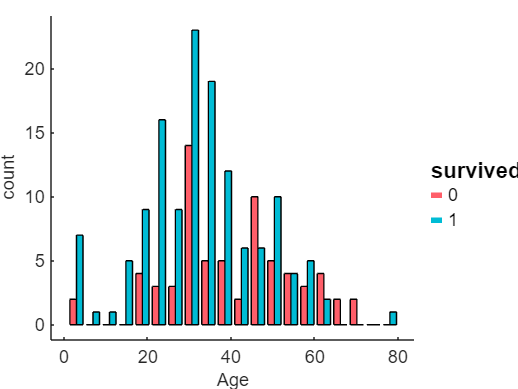

ans =   gramm with properties:

     legend_axe_handle: [1×1 Axes]
      title_axe_handle: []
    facet_axes_handles: [1×1 Axes]
               results: [1×1 struct]


g.draw()

#### 3.3 Fare Distribution by class

figure;
g=gramm("x",data.Pclass,"y",data.Fare,"color",data.Pclass)

g =   gramm with properties:

     legend_axe_handle: []
      title_axe_handle: []
    facet_axes_handles: []
               results: []


g.stat_boxplot()

ans =   gramm with properties:

     legend_axe_handle: []
      title_axe_handle: []
    facet_axes_handles: []
               results: [1×1 struct]


g.set_names("x","Pclass","y","Fare")

ans =   gramm with properties:

     legend_axe_handle: []
      title_axe_handle: []
    facet_axes_handles: []
               results: [1×1 struct]


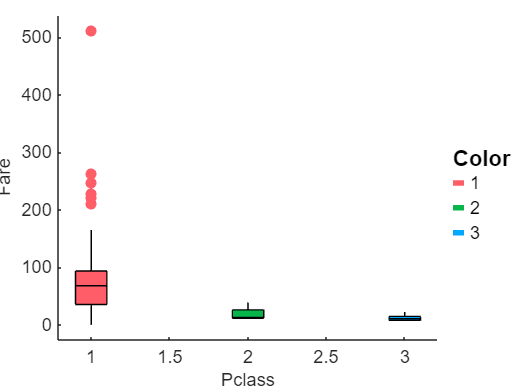

ans =   gramm with properties:

     legend_axe_handle: [1×1 Axes]
      title_axe_handle: []
    facet_axes_handles: [1×1 Axes]
               results: [1×1 struct]


g.draw()

#### 3.4 Survival Rate by Class

figure
g=gramm("x",data.Pclass,"color",data.Survived)

g =   gramm with properties:

     legend_axe_handle: []
      title_axe_handle: []
    facet_axes_handles: []
               results: []


g.stat_bin("geom","bar","dodge",1)

ans =   gramm with properties:

     legend_axe_handle: []
      title_axe_handle: []
    facet_axes_handles: []
               results: [1×1 struct]


g.set_names("x","Pclass","y","count","color","survived")

ans =   gramm with properties:

     legend_axe_handle: []
      title_axe_handle: []
    facet_axes_handles: []
               results: [1×1 struct]


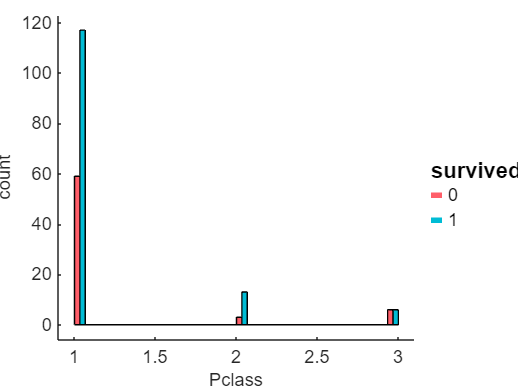

ans =   gramm with properties:

     legend_axe_handle: [1×1 Axes]
      title_axe_handle: []
    facet_axes_handles: [1×1 Axes]
               results: [1×1 struct]


g.draw()

#### 3.5 Scatter plot : Age vs Fare

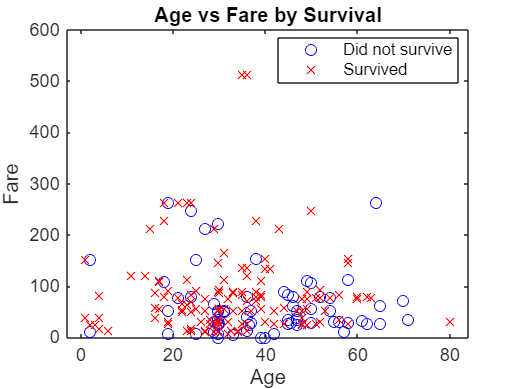

figure
gscatter(data.Age,data.Fare,data.Survived,"br","ox")
xlabel("Age")
ylabel("Fare")
title("Age vs Fare by Survival")
legend("Did not survive","Survived")

#### Correlation Matrix

% Compute correlation matrix for numerical variable
num_var = data{:, {'Age', 'SibSp', 'Parch', 'Fare'}}

num_var =    38.0000    1.0000         0   71.2833
   35.0000    1.0000         0   53.1000
   54.0000         0         0   51.8625
    4.0000    1.0000    1.0000   16.7000
   58.0000         0         0   26.5500
   34.0000         0         0   13.0000
   28.0000         0         0   35.5000
   19.0000    3.0000    2.0000  263.0000
   29.6991    1.0000         0  146.5208
   49.0000    1.0000         0   76.7292


correlationMatrix = corr(num_var, 'Rows', 'complete')

correlationMatrix =     1.0000   -0.1453   -0.2504   -0.0756
   -0.1453    1.0000    0.2654    0.2907
   -0.2504    0.2654    1.0000    0.3840
   -0.0756    0.2907    0.3840    1.0000


disp('Correlation Matrix:')

Correlation Matrix:


disp(correlationMatrix)

    1.0000   -0.1453   -0.2504   -0.0756
   -0.1453    1.0000    0.2654    0.2907
   -0.2504    0.2654    1.0000    0.3840
   -0.0756    0.2907    0.3840    1.0000



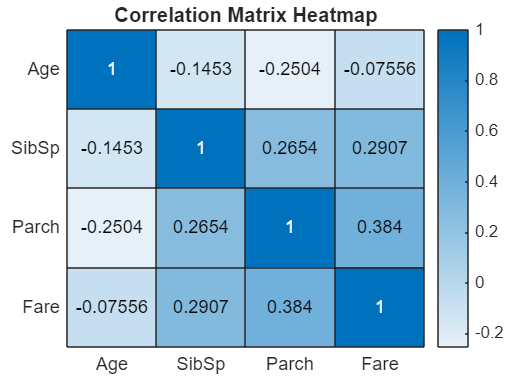


% Display heatmap of the correlation matrix
figure;
heatmap(correlationMatrix, 'XData', {'Age', 'SibSp', 'Parch', 'Fare'}, 'YData', {'Age', 'SibSp', 'Parch', 'Fare'})
title('Correlation Matrix Heatmap')

## 4.Pattern Identification

- Survival rate is higher for females compared to males

- Passengers in hiher classes(1st class) have a higher survival rate

- There is a positive correlation between fare and class

- Younger passengers have a slightly higher chance of survival